close all; clear; clc;

# Utilizing the file Spreadsheet

**created by:** 2019, Edmonds

**last updated on:** 20190220

**primary purpose:**  The purpose of this script is to make calculations and generate plots based upon the current file spreadsheet of settled points

**Instructions:** To add a new data set to the file_Spreadsheet_v1_20190207 spreadsheet:

- Find and replace "file_Spreadsheet_v1_20190207" with the current file_Spreadsheet_v1_20190207 spreadsheet. 

- Find and replace "MEGA_27x88_1b_1090_set_1" with new data MEGA_27x88_1b_1090_set_1

- **Make appropriate modifications to Section 3** (if motor or rotor was replaced and/or tests were taken on a new day the parameters will need to be entered)

- Add to Section 1 as needed (e.g., when tests are recorded on a new day, add the new density)

**Notes:**

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

This should only be used for 

load('New_Master_20190220.mat');
file = New_Master_20190220(:,:);
% Note: this should be a .mat file above
    % May be necessary to open the xls file in matlab 
     % and save it as a numeric matrix
MotorInertia = file(:,1);                       % [sec]
MotorMass = file(:,2);                        % [micro sec]
RotorInertia = file(:,3);                          % [ft.lbf]
RotorMass = file(: ,4);                          % [lbf]
RotorDia = file(:,5);                    % [Volts]
DiskArea = file(:,6);                    % [Amps]
RotorPitch = file(:,7);              % [RPM]
BladeNo = file(:,8);

PWM = file(:,9);                     % [us]
Q = file(:,10);                   % [ft.lbf/sec]
T = file(:,11);                   % [lbf]         
V = file(:,12);                     % [V]
I = file(:,13);                 % [Amps]
RPM = file(:,14);                  % [RPM]
% convert to RPM for plotting purposes -- not in spreadsheet
rad = RPM .* (pi/30);           % [rad/sec]

P_in_W = file(:,15);               % [Watts] 
% convert to ft.lbf -- not in spreadsheet
P_in = P_in_W .* 7478;                 % [ft.lbf]
% convert to ft.lbf -- not in spreadsheet
P_out_W = file(:,16);                  % [W]
P_out = P_out_W .* 0.7478;             % [ft.lbf]

Motor_Eff = file(:,17);                % [%]
Prop_Eff = file(:,18);                % [%]
Overall_Eff = file(:,19);                % [%]
ESC_Temp = file(:,20);                % [F]
Motor_Temp = file(:,21);                % [F]
ST = file(:,22);                    % [sec]
MaxAcc = file(:,23);                    % [RPM/sec^2]
p = file(:,24);                     % [slug]

% Calculations (the initial ones were made in excel)
deltaV = file(:,25);
deltaI = file(:,26);
deltaRPM = file(:,27);
deltaP_in_W = file(:,28);
deltaP_out_W = file(:,29);
deltaPWM = file(:,30); 
deltaT = file(:,31);
deltaQ = file(:,32);


disk_loading = T ./ DiskArea;                     % [lb/sq.ft]]
throttle = (PWM - 1000) ./ 10;
radius = RotorDia ./ 2;

C_T = T ./ (p .* DiskArea .* (rad .* radius) .^2);
C_P = P_out ./ (p .* DiskArea .* (rad .* radius).^3);
C_Q = Q ./ (p .* DiskArea .* (rad .* radius).^(2) .* radius);


k = 1.15;
C_T_theory = linspace(0, 0.02, 1000);
C_P_theory = C_T_theory .^(3/2) ./ sqrt(2);
C_Pi = k .* (C_T_theory .^(3/2) ./ sqrt(2));


C_P vs C_T plot

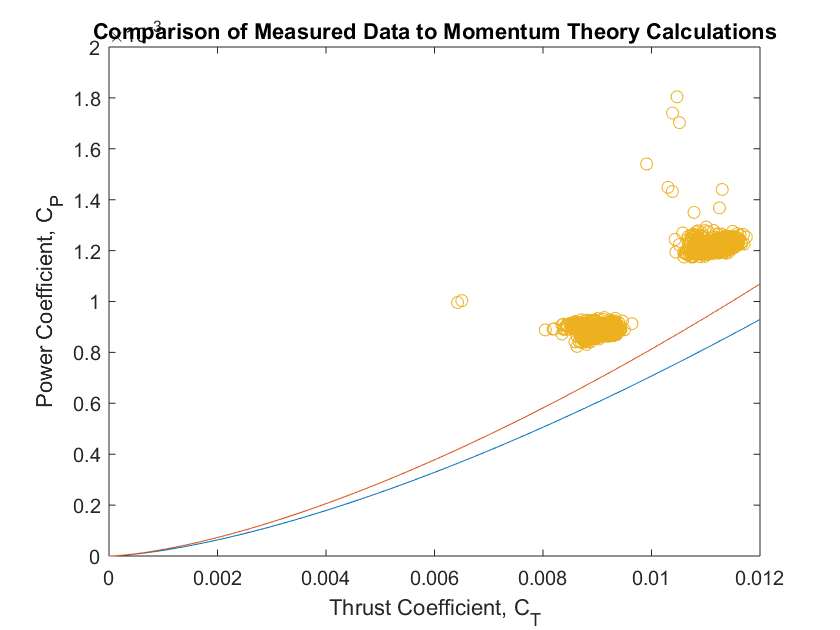

figure(100)
plot(C_T_theory, C_P_theory, C_T_theory, C_Pi,...
    C_T, C_P, 'o');
title('Comparison of Measured Data to Momentum Theory Calculations');
xlabel('Thrust Coefficient, C_T'); ylabel('Power Coefficient, C_P');
xlim([0 0.012]); ylim([0 0.002]);